## Control of a 2D quadcopter

In this tutorial, we will control a 2D quadcopter (pictured below) to complete increasingly difficult tasks.

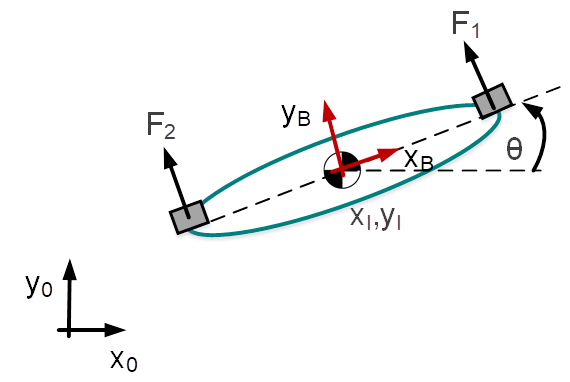

We will,

- model the quadcopter, and calculate its equations of motion using the manipulator equations

- linearise the model

- stabilize the linearized model using LQR

- control an augmented model which tracks position commands, again using LQR

- control a model (linearized in yet another way) such that it intercepts a falling ball, again using LQR, but with the addition of Proportional Navigation

In each case we begin with a simulation of the linear model approximation using MATLAB, before implementing the controller on the accurate, nonlinear model. You will need Simulink and the Control Toolbox

You may want to comment out some simulation/plotting after seeing it run, if you find the file is running slowly. Also, make sure to look at the simulink files in detail to understand the actual implementation. Finally, please provide feedback so that we know what to improve!

syms x y th dx dy dth ddx ddy ddth F1 F2 'real'
syms mass width g inertia 'real'

q = [x; y; th];
dq = [dx; dy; dth];
ddq = [ddx; ddy; ddth];

### Define positions, velocities, energies

% position and velocity
pBody = [x;
         y];

vBody = jacobian(pBody, q) * dq;

% potential energy
Ttot = 0.5*mass*transpose(vBody)*vBody ...
    + 0.5*inertia*(dth)^2;
Ttot = simplify(Ttot)

$$Ttot = \frac{\mathrm{inertia}\,{\mathrm{dth}}^{2}}{2}+\frac{\mathrm{mass}\,{\mathrm{dx}}^{2}}{2}+\frac{\mathrm{mass}\,{\mathrm{dy}}^{2}}{2}$$


% kinetic energy
Vtot = mass*[0 g]*pBody

$$Vtot = g\,\mathrm{mass}\,y$$

### Manipulator equation terms

Hopefully everyone is familiar with them by now. See how we use the same code every time! The hard work is finding the positions, velocities and energies

M = simplify(hessian(Ttot, dq));

dM = sym(zeros(size(M)));
for i = 1:size(dM, 1)
    for j = 1:size(dM, 2)
        dM(i,j) = jacobian(M(i,j), q) * dq;
    end
    
end
dM = simplify(dM);

C = dM*dq - transpose(jacobian(Ttot, q));
C = simplify(C);

G = simplify(jacobian(Vtot, q)');

### Q input matrix

For the two input forces: propellers!

% rotation matrix
R = [ cos(th) -sin(th)
      sin(th)  cos(th)];
 
% location of the input forces
r1 = [x; y] + R * [ width/2; 0];
r2 = [x; y] + R * [-width/2; 0];

% input force with respect to inertia
f1 = R * [0; F1];
f2 = R * [0; F2];

% partial derivatives
Q1 = simplify(f1' * jacobian(r1, q))';
Q2 = simplify(f2' * jacobian(r2, q))';

% calculate B matrix
B = jacobian(Q1 + Q2, [F1;F2]);

### Linearise the model

The operating point is $x = dx = y = dy = th = dth = 0$ and hovering, so the thrust is shared between the two rotors

We'll start by using the manipulator equation terms defined above to find the equations of motion for the system. `dyn` is essentialy the same as $\dot{x} = \cdots$ in a statespace equation. The elements correspond to 'state' 'inputs' 'outputs' in the following cell

u = [F1; F2];

% the backslash operator \ solves the equation Ax = b
% more efficienctly than x = inv(A) * b
acceleration_eqns = simplify(M \ (-C - G + B*u))

$$acceleration\_eqns = \left(\begin{array}{c} -\frac{\sin\left(\mathrm{th}\right)\,\left(F_{1}+F_{2}\right)}{\mathrm{mass}}\\ \frac{F_{1}\,\cos\left(\mathrm{th}\right)-g\,\mathrm{mass}+F_{2}\,\cos\left(\mathrm{th}\right)}{\mathrm{mass}}\\ \frac{\mathrm{width}\,\left(F_{1}-F_{2}\right)}{2\,\mathrm{inertia}} \end{array}\right)$$

dyn = [acceleration_eqns; dq];

% Jacobian of dynamics, with the operating point subbed in
A = jacobian(dyn, [dq.', q.']);
A = subs(A, [dq.', q.', u.'], [0,0,0,0,0,0,mass*g/2,mass*g/2]);

B = jacobian(dyn, [u.']);
B = subs(B, [dq.',q.',u.'],[0,0,0,0,0,0,mass*g/2,mass*g/2]);

Substitue in specific parameters

% Params needed for simulation
m_ = 1;
w_ = 0.2;
I_ = 1/12 * m_ * w_^2;
g_ = 9.81;

% Subsitute to get numerical A and B
A = double(subs(A, [mass,width,inertia,g], [m_,w_,I_,g_]));
B = double(subs(B, [mass,width,inertia,g], [m_,w_,I_,g_]));

C = eye(6);

D = [];

states = {'dx' 'dy' 'dth' 'x' 'y' 'th'};
inputs = {'u1' 'u2'};
outputs = {'dx' 'dy' 'dth' 'x' 'y' 'th'};

sys_ss = ss(A, B, C, D, 'statename', states,...
                        'inputname', inputs,...
                        'outputname', outputs)

sys_ss =
 
  A = 
           dx     dy
   dx       0      0
   dy       0      0
   dth      0      0
   x        1      0
   y        0      1
   th       0      0
 
          dth      x
   dx       0      0
   dy       0      0
   dth      0      0
   x        0      0
   y        0      0
   th       1      0
 
            y     th
   dx       0  -9.81
   dy       0      0
   dth      0      0
   x        0      0
   y        0      0
   th       0      0
 
  B = 
         u1   u2
   dx     0    0
   dy     1    1
   dth   30  -30
   x      0    0
   y      0    0
   th     0    0
 
  C = 
         dx   dy  dth
   dx     1    0    0
   dy     0    1    0
   dth    0    0    1
   x      0    0    0
   y      0    0    0
   th     0    0    0
 
          x    y   th
   dx     0    0    0
   dy     0    0    0
   dth    0    0    0
   x      1    0    0
   y      0    1    0
   th     0    0    1
 
  D = 
        u1  u2
   dx    0   0
   dy    0   0
   dth   0   0
   x     0   0
   y  

### LQR - Linear Quadratic Regulator

Stabilises states!

Q = eye(6);
Q(4,4) = 500;
Q(5,5) = 500;
Q(6,6) = 500;
R = eye(2);

% calculate LQR gain

K = lqr(A, B, Q, R)

K =    -8.1525    4.0387    1.0872  -15.8114   15.8114   20.4631
    8.1525    4.0387   -1.0872   15.8114   15.8114  -20.4631


Find the closed loop system

Ac = [(A-B*K)];
Bc = [B];
Cc = [C];
Dc = [D];

sys_cl = ss(Ac, Bc, Cc, Dc, 'statename', states,...
                            'inputname', inputs,...
                            'outputname', outputs);

Simulate the linearised system with LQR, and then plot the result. Note that this isn't the actual fully nonlinear system! And it's not *controlling* the states, just stabilizing them

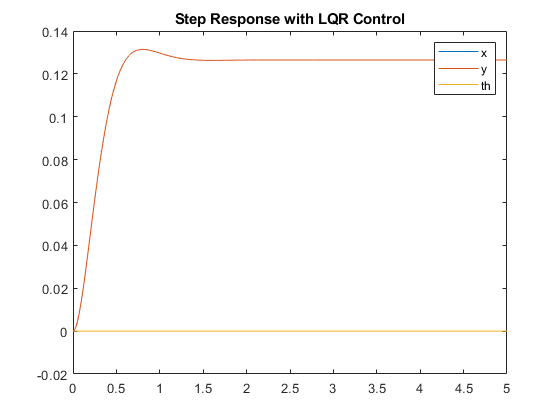

t = 0:0.001:5;
r = 2*ones(length(t), 2);
[y,t,x] = lsim(sys_cl, r, t);

% plot the position states
plot(t, y(:, 4:6));
legend(["x"; "y"; "th"]);
title('Step Response with LQR Control')

### Augmented Linear Quadratic Regulator

Now, let's add integrator states (one integrator for x and one for y errors). Standard state feedback stuff: http://cse.lab.imtlucca.it/~bemporad/teaching/ac/pdf/08-integral-action.pdf

% New integrator states for error on positions x and y
newA = [0, 0, 0, 1, 0, 0, 0, 0;...
        0, 0, 0, 0, 1, 0, 0, 0];
tempA = horzcat(A, zeros(6,2));

% New A Matrix (aug = augmented)
A_aug = vertcat(tempA, newA);

% New B Matrix
B_aug = vertcat(B, zeros(2,2));

% New C matrix
C_aug = eye(8);

% weighting system - Weighting integral states more
% for SS tracking
Q = eye(8);
Q(4,4) = 10;
Q(5,5) = 10;
Q(6,6) = 10;
Q(7,7) = 100;
Q(8,8) = 100;

R = eye(2);

% calculate new LQR gain
K_aug = lqr(A_aug, B_aug, Q, R)

K_aug =    -3.1788    2.6488    0.8667   -7.0679    6.5161    7.5326   -7.0711    7.0711
    3.1788    2.6488   -0.8667    7.0679    6.5161   -7.5326    7.0711    7.0711


Now, let's simulate the augmented system:

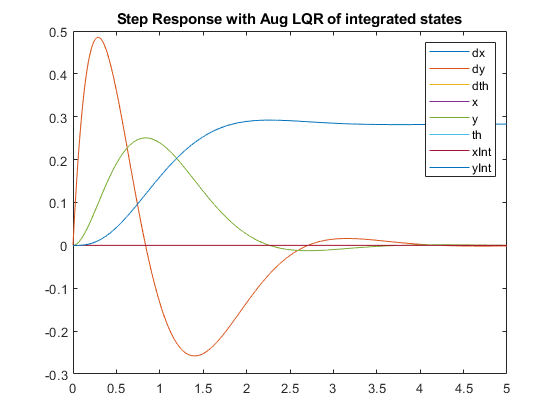

Ac = [(A_aug - B_aug*K_aug)];
Bc = [B_aug];
Cc = [C_aug];
Dc = [D];

states = {'dx' 'dy' 'dth' 'x' 'y' 'th' 'xInt' 'yInt'};
inputs = {'u1' 'u2'};
outputs = {'dx' 'dy' 'dth' 'x' 'y' 'th' 'xInt' 'yInt'};

sys_cl = ss(Ac, Bc, Cc, Dc, 'statename', states,...
                            'inputname', inputs,...
                            'outputname', outputs);

t = 0:0.001:5;
r = 2*ones(length(t), 2);
[y,t,x] = lsim(sys_cl, r, t);
plot(t, y);
legend(states)
title('Step Response with Aug LQR of integrated states')

### Accurate simulation

The next step is to simulate the fully nonlinear system, and animate the result

% these constants must be in your workspace for the
% Simulink model
m = m_;
g = g_;
I = I_;
L = w_;

% you might want to copy-paste the final commands
% into the Command Window to avoid having to re-run
% all the above code every time
% OTHERWISE just commenting out the plots above
% should speed things up enough

% run the regular LQR
%sim('quad_LQR_sim.slx');

% run augmented LQR
% sim('quad_LQRwithIntegrators_sim.slx');

% plot!
%anim_2Dquad;

Now, let's take the controller to the next level...

## Intercept a moving target

Comment out the `sim` and `anim_2Dquad` lines in the cell above

We're going to linearize as before, but only consider the roll dynamics (th and dth)

% Operating point is zeros and HOVERING, so thrust
% shared among two rotors.
u = [F1; F2];
dyn = [acceleration_eqns(3); dth];
dyn = subs(dyn, [mass,width,inertia,g], [m_,w_,I_,g_])

$$dyn = \left(\begin{array}{c} 30\,F_{1}-30\,F_{2}\\ \mathrm{dth} \end{array}\right)$$


% OUTPUTS are acceleration: ddx, ddy
Y = subs(acceleration_eqns(1:2), [mass,width,inertia,g], [m_,w_,I_,g_])

$$Y = \left(\begin{array}{c} -\sin\left(\mathrm{th}\right)\,\left(F_{1}+F_{2}\right)\\ F_{1}\,\cos\left(\mathrm{th}\right)-g+F_{2}\,\cos\left(\mathrm{th}\right) \end{array}\right)$$

Find A, B, C, D for state space equations:

A = jacobian(dyn, [dth, th]);
A = subs(A,[dth, th, u.'],[0,0,m*g/2,m*g/2]);

B = jacobian(dyn, [u.']);
B = subs(B,[dth, th, u.'],[0,0,m*g/2,m*g/2]);

% this time weed to linearise the output equation
C = jacobian(Y, [dth, th]);
C = subs(C,[dth, th, u.'],[0,0,m*g/2,m*g/2]);

% and linearise feedforward
D = jacobian(Y, [u.']);
D = subs(D,[dth, th, u.'],[0,0,m*g/2,m*g/2]);

Next, we augment the Jacobian with integral states for accelerations

newA = [0, -g, 0, 0;...
        0,  0, 0, 0];
tempA = horzcat(A, zeros(2,2));

% New A Matrix
A_aug = vertcat(tempA, newA);

% New B Matrix
B_aug = vertcat(B, D);

% New C Matrix
newC = [0, 0, 0, 0;...
        0, 0, 0, 0];
tempC = horzcat(C,zeros(2,2));
C_aug = vertcat(tempC, newC);

% New D Matrix - STAYS THE SAME
D_aug = vertcat(D, zeros(2,2));

% get numerical versions (right now they're symbolic)
A = double(A_aug);
B = double(B_aug);
C = double(C_aug);
D = double(D_aug);

% linearized system
states = {'dth' 'th' 'ddxE' 'ddyE'};
inputs = {'u1' 'u2'};
outputs = {'ddx' 'ddy' 'ddxE' 'ddyE'};

sys_ss = ss(A, B, C, D, 'statename', states,...
                        'inputname', inputs,...
                        'outputname', outputs)

sys_ss =
 
  A = 
           dth     th
   dth       0      0
   th        1      0
   ddxE      0  -9.81
   ddyE      0      0
 
          ddxE   ddyE
   dth       0      0
   th        0      0
   ddxE      0      0
   ddyE      0      0
 
  B = 
          u1   u2
   dth    30  -30
   th      0    0
   ddxE    0    0
   ddyE    1    1
 
  C = 
           dth     th
   ddx       0  -9.81
   ddy       0      0
   ddxE      0      0
   ddyE      0      0
 
          ddxE   ddyE
   ddx       0      0
   ddy       0      0
   ddxE      0      0
   ddyE      0      0
 
  D = 
         u1  u2
   ddx    0   0
   ddy    1   1
   ddxE   0   0
   ddyE   0   0
 
Continuous-time state-space model.



Finally - let's test the linearized version of the quadcopter model

% LQR - regulator/stabilising states
Q = eye(4);
Q(3,3) = 200;
Q(4,4) = 200;
R = eye(2);

% calculate LQR gain
K = lqr(A, B, Q, R)

K =     0.9814   13.8943  -10.0000   10.0000
   -0.9814  -13.8943   10.0000   10.0000


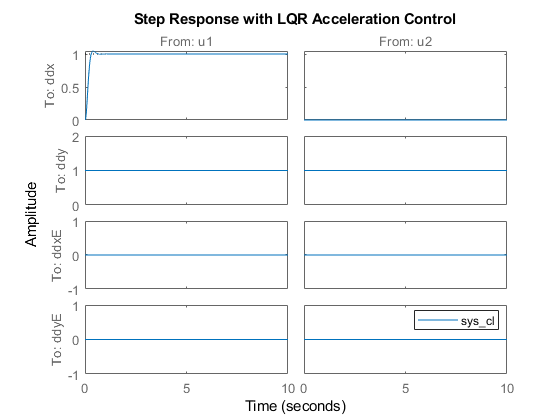


% closed loop
Ac = [(A-B*K)];
Br = [0 0; 0 0; -1 0; 0 -1];
Cc = [C];
Dc = [D];

sys_cl = ss(Ac, Br, Cc, Dc, 'statename', states,...
                            'inputname', inputs,...
                            'outputname', outputs);

t = 0:0.001:10;
step(sys_cl, t)
legend
title('Step Response with LQR Acceleration Control')

Finally - let's simulate the fully complex system again and animate the results. You can just copy-paste these two lines into the Command Window if you don't want to rerun everything above. Make sure to look at the Simulink file -- it's a step up in complexity from the previous ones, but all of the contol stuff should essentially be a real-world application of all of your 3rd year control courses - full-state feedback, integrator states, etc. Revise your notes! Perhaps write out equations by hand! And good luck!

% sim('quad_LQRaccControl_sim.slx');
% anim_2Dquad_intercept;